# This script is intended to introduce plotting as the most elementary visualization techinuque of Matlab.

## Data definition

### Creating vectors representing trigonometric functions

Creating abscissa (x) values of the functions:

angleVect = 0 : 0.05 * pi : 2 * pi;

Creating ordinate (y) values of three trigonometric functions:

sine = sin(angleVect);
sine2 = 2 * sin(0.5 * angleVect + pi / 8);
cosine = 0.5 * cos(2 * angleVect - pi / 6);

## Creating figure (window for visualization) and axis (coordinate sytem)

### Creating figure and setting its properties

figureObject = figure;
figureObject.Name = 'Trigonometric functions';
figureObject.Color = 'white';
figureObject.Units = 'normalized';
figureObject.Position = [0.1, 0.1, 0.8, 0.75];

Consider printing sizes:

widthOfFig = 8; % cm
heightOfFig = 5; % cm

figureObject.PaperUnits = 'centimeters';
figureObject.PaperPosition = [0, 0, widthOfFig, heightOfFig];
figureObject.PaperSize = [widthOfFig, heightOfFig];

Other form:

### Creating axis and setting its properties

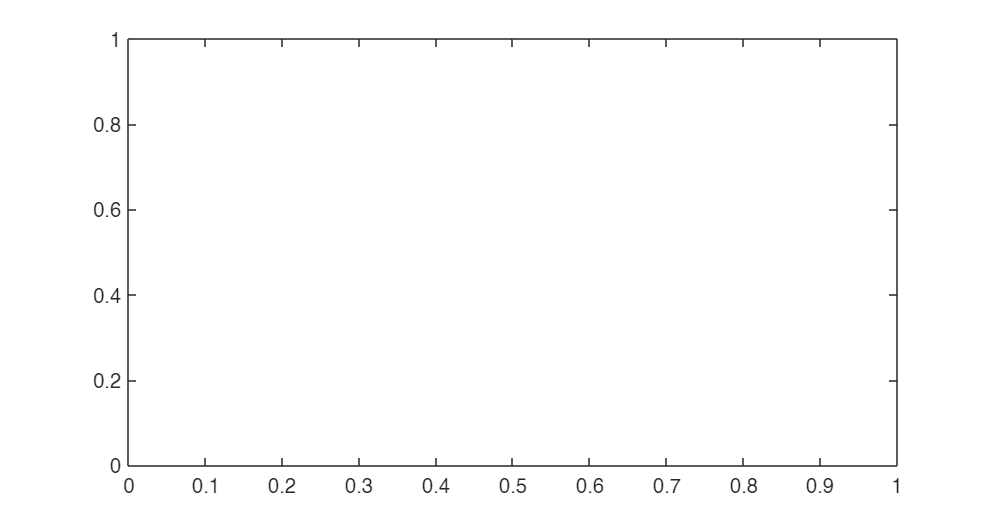

fontSize = 8;

axisObject = axes(figureObject);
axisObject.FontSize = 12;
axisObject.FontWeight = 'Normal';
axisObject.TitleFontWeight = 'Bold';
axisObject.TitleFontSizeMultiplier = 1.2;
axisObject.LabelFontSizeMultiplier = 1.0;
axisObject.Box = 'on';

Other form

## Plotting (2D line visualization)

Holding the axis to plot more than one 'curves'

hold(axisObject, 'on') 

Plotting sine function over angle with solid blue line, 'o' markers

plot(axisObject, angleVect, sine, 'b-o');

Plotting sine function over angle with green '*' markers (without connecting line)

plot(axisObject, angleVect, sine2, 'g*');

Detailed settings of plot

plot(axisObject, angleVect, cosine, 'Color', [20, 100, 200] / 255, 'LineStyle', '-.', 'LineWidth', 2, ...
    'Marker', 's', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'g', 'MarkerSize', 10);

Release the axis

hold(axisObject, 'off')

Put grid on axis because it look nice :)

grid(axisObject, 'on');

Labels and title

title(axisObject, 'Trigonometric functions');
xlabel(axisObject, 'angle [°]');
ylabel(axisObject, 'A [m]');
legend(axisObject, {'sin1', 'sin2', 'cos'}, 'FontSize', 12, 'Orientation', 'Vertical', ...
    'Location', 'Best');

Setting of axis values and ticks

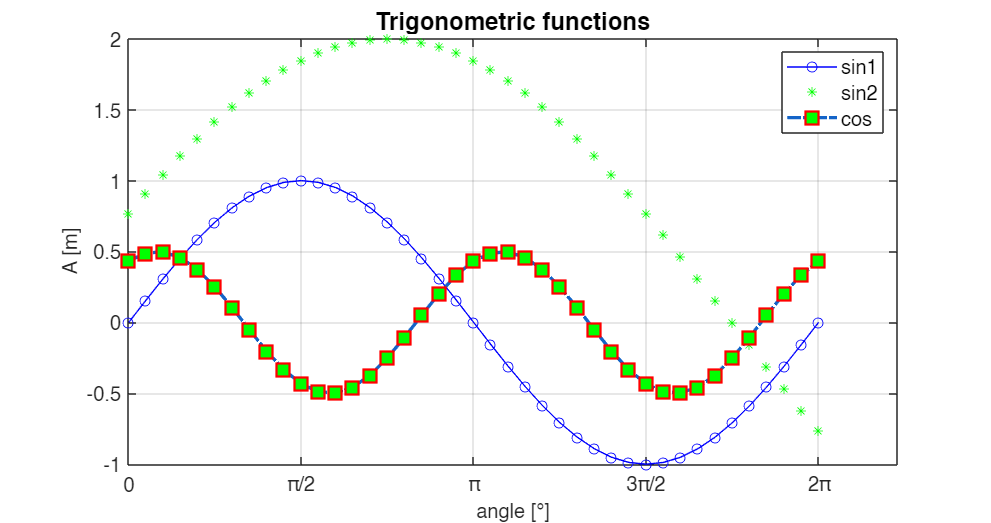

axisObject.XTick = [0, pi/2, pi, 3*pi/2, 2*pi];
axisObject.XTickLabel = {'0', '\pi/2', '\pi', '3\pi/2', '2\pi'};

## Save graphics

### Vector graphics

                      figure                  file name              format        rendering

print(figureObject, 'myFigure.emf', '-dmeta', '-painters'); % for Word documents
print(figureObject, 'myFigure.pdf', '-dpdf', '-painters');  % for LaTeX documents

### Pixel graphics

print(figureObject, 'myFigure.png', '-dpng', '-opengl');

## Creating subplots

Subplots are useful when one wants to create corresponding plots on different coordinate systems.

Let's create two coordinate systems under each other! Multiple coordinate systems in a given layout can be created with $\texttt{subplot(m,n,p)}$ function, where $\texttt{m}$, $\texttt{n}$ denotes the number of vertically and horizontally aligned axes and $\texttt{p}$ is the index of the current coordinate system.

Creating the first coordinate system (axis) with vertical alignment (2 rows, 1 columns):

axis1 = subplot(2, 1, 1);
plot(axis1, angleVect, sine, 'b-o');

Creating the second coordinate system (axis) with vertical alignment (2 rows, 1 columns):

axis2 = subplot(2, 1, 2);
plot(axis2, angleVect, sine2, 'g:d');

Plot title and labels:

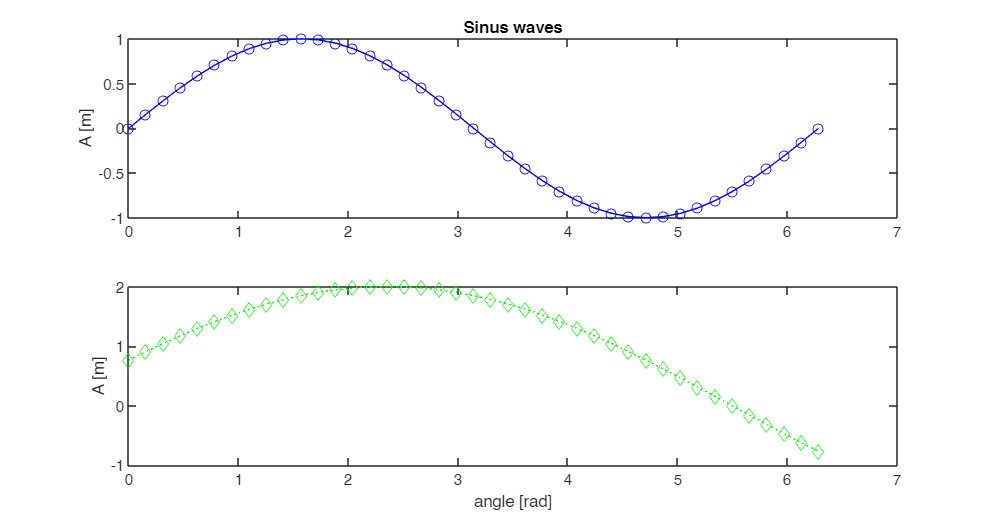

title(axis1, 'Sinus waves');
xlabel(axis2, 'angle [rad]');
ylabel(axis2, 'A [m]');
ylabel(axis1, 'A [m]');